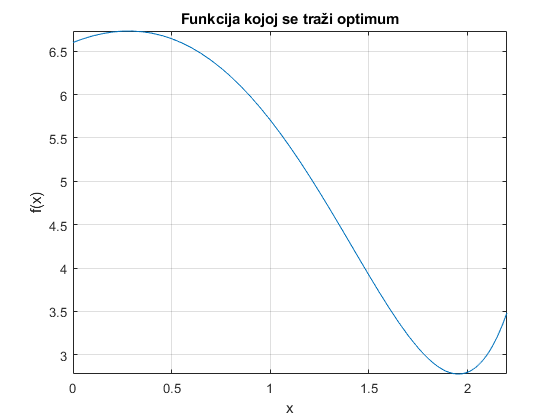

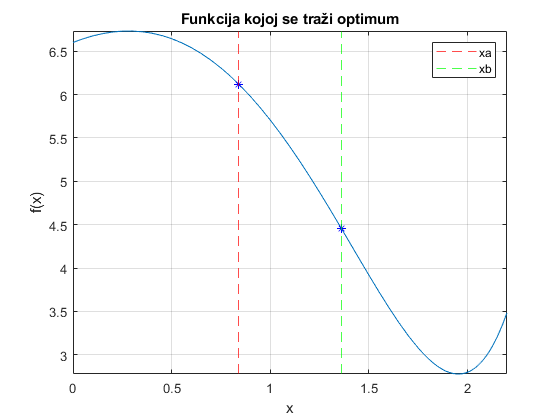

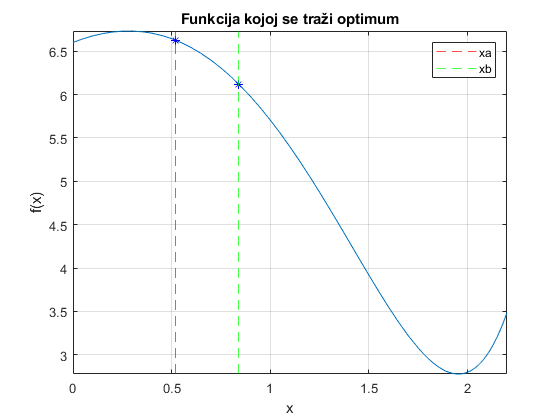

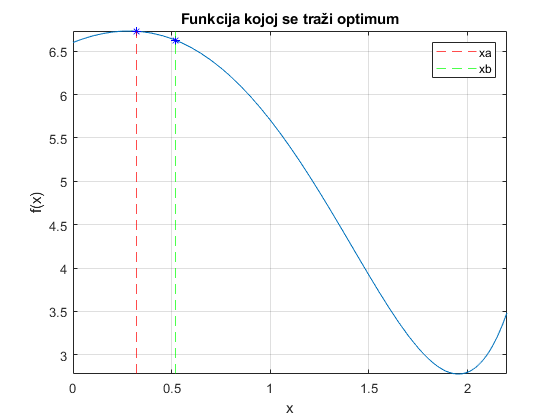

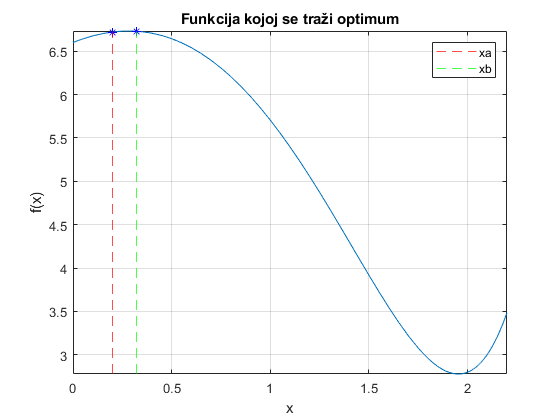

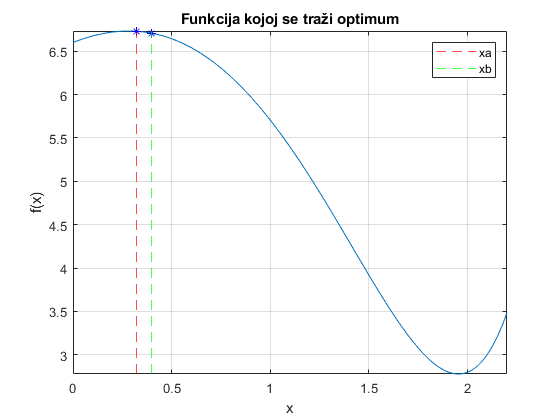

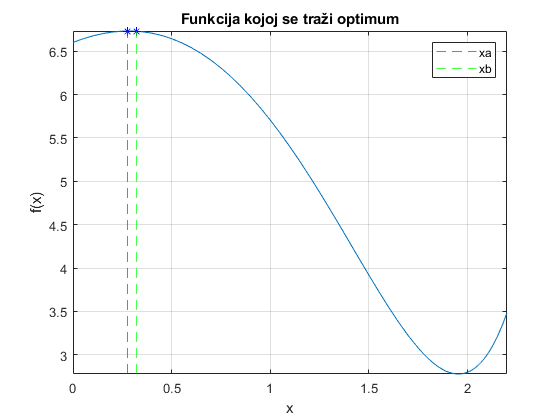

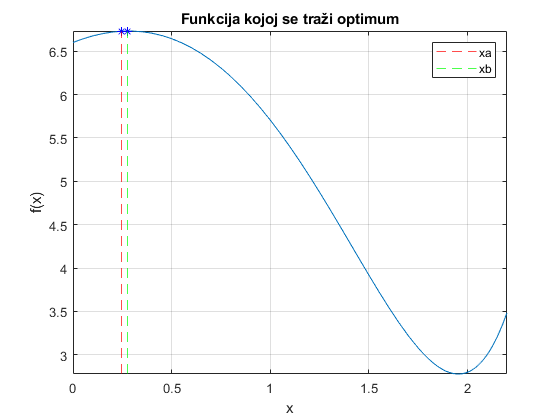

f = @(x) 1.4.*exp(x).*(x-2).^2+0.9.*x+1;
%f = @(x) (x-1).^2; %min u 1
%f = @(x) -(x-1).^2+1; % max u 0.5
fplot(f,[0 2.2])
a=gca;
xlabel('x')
ylabel('f(x)')
title('Funkcija kojoj se traži optimum')
grid on
xL=0;
xU=2.2;
In=0.1;
%In=0.01; % promjena intervala u kojem tražimo rješenje
Ip=xU-xL;
n=Ip/In;
i=1;
k=0;
j=1;
while i<n
   l=k+j;
   F(i)=l;
   k=j;
   j=l;
   i=i+1;
end
Ik=Ip;
I=Ip;
for m=2:(i-1)
    while I>In
    I=F(i-m)/F(i-m+1)*Ik;
    Ik=I;
    xa=xU-I;
    xb=xL+I;
    f2 = figure;
    a2 = copyobj(a,f2);
    hold on
    Xa=xline(xa,'--r');
    Xb=xline(xb,'--g');
    plot(xa,f(xa),'*','color','b')
    plot(xb,f(xb),'*','color','b')
    xlabel('x')
    ylabel('f(x)')
    title('Funkcija kojoj se traži optimum')
    legend([Xa(1) Xb(1)],'xa','xb')
    grid on
    hold off
    if f(xa)<f(xb)
        %xU=xb; % ukoliko se traži minimum
        xL=xa;
    end
    if f(xa)>f(xb)
        %xL=xa; % ukoliko se traži minimum
        xU=xb;
    end  
    end
end

%fprintf('Pronađen je minimum!\nx = %.4f \nf(x) = %.4f',(xL+xU)/2,f((xL+xU)/2))
fprintf('Pronađen je maximum!\nx = %.4f \nf(x) = %.4f',(xL+xU)/2,f((xL+xU)/2))

Pronađen je maximum!
x = 0.2452 
f(x) = 6.7297